# Análise de espaço de estados

clear all;
close all;
clc;


## Definindo o modelo não linear


% Definido em um bloco Simulink - SIR

beta = 1e-3;
r = 1e-1;
N = 500;

S0 = 499;
I0 = 1;
R0 = 0;

options = simset('solver','ode45','MaxStep',0.01,'InitialStep',0.01,'ReturnWorkspaceOutputs', 'on');
y = sim('SIRmodel',100,options);


## Visualização

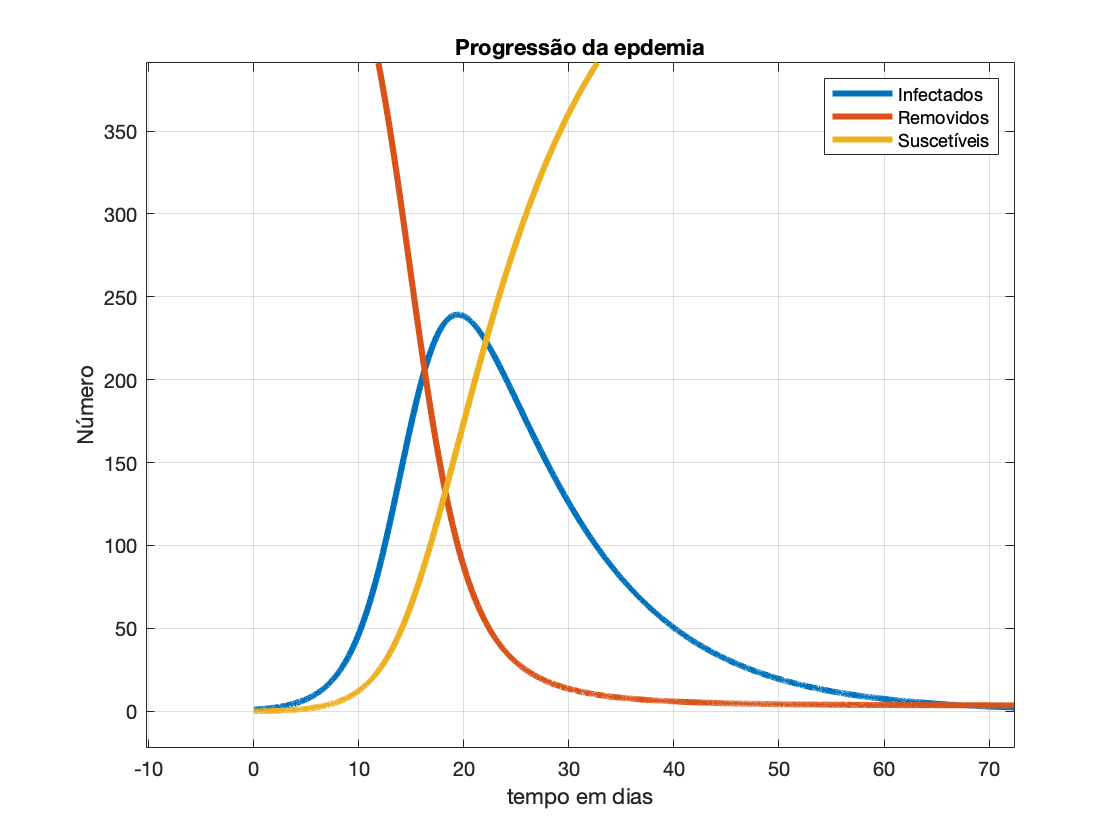

I = y.logsout{1}.Values.Data; % Saída I
S = y.logsout{2}.Values.Data; % Saída S
R = y.logsout{3}.Values.Data; % Saída R
t = y.tout;

figure()
plot(t,I,t,R,t,S,'LineWidth',3);
grid;
legend('Infectados','Removidos','Suscetíveis');
xlabel('tempo em dias')
ylabel('Número')
title('Progressão da epdemia')

## Linearizar o modelo

% Condições de linearização

beta0 = 1e-3;
r0    = 0.1;

[A,B,C,D] = linmod('SIRsim')

A =    -0.0010   -0.4990         0
    0.0010    0.3990         0
         0    0.1000         0


B =   -499     0
   499    -1
     0     1


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0
     0     0
     0     0


## Propriedades do modelo linear

[V,D,W] = eig(A)                % auto valroes e auto vetores

V =          0   -0.7718    0.7080
         0    0.6167   -0.0018
    1.0000    0.1551   -0.7062


D =          0         0         0
         0    0.3977         0
         0         0    0.0003


W =     0.5774    0.0025    0.6243
    0.5774    1.0000    0.7812
    0.5774         0         0


obsv(A,C)       % observabilidade

ans =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
   -0.0010   -0.4990         0
    0.0010    0.3990         0
         0    0.1000         0
   -0.0005   -0.1986         0
    0.0004    0.1587         0
    0.0001    0.0399         0


rank(obsv(A,C))    % sistema observável

ans = 3

## Discretização do modelo linear


$$x(k+1) = Hx(k) + Gu(k)
$$



$$H  = e^{AT_a}$$



$$G = \int_0^{T_a} e^{A \times \tau} B d \tau$$


Ta = 1;                 % taxa de amostragem diária

H = exp(A*Ta)

H =     0.9990    0.6071    1.0000
    1.0010    1.4903    1.0000
    1.0000    1.1052    1.0000


## Análise da dados reais